rng(0);
clear;

Read all instructions before you start. Generate N points (with N- taking the values 10, 102 , 103 , 104 , 105 ) from a multivariate 2D Gaussian probability density function with mean µ = [1, 2]'

N = [10,10^2,10^3,10^4,10^5];
mean = [1;2];

 and a covariance matrix C with the first row as [1.6250, -1.9486] and the second row as [-1.9486, 3.8750]. For this generation, you are only allowed to use the randn() and eig() functions in Matlab. 

C = [1.6250, -1.9486;-1.9486, 3.8750];

For each data sample of size N, compute the maximum-likelihood (ML) estimates of the mean and the covariance matrix. For this estimation, you are only allowed to use the sum() function in Matlab. 

(a) (5 points) Describe and justify your method for generating sample points from the 2D Gaussian. 

p(x) = 1/2pisqrt(|C|) exp(-(x-mean)'C-1(x-mean)/2)

C = QDQ'

C-1 = QD-1Q'

y = (Q'(x-mean)), then

p(y)= 1/2pisqrt(|D|)exp(-y'D-1y/2)

Y~ gaussian(0,sqrt(D(1))),gaussian(0,sqrt(D2) 

X ~ QY + mu

[Q,D] = eig(C)

Q =    -0.8660   -0.5000
   -0.5000    0.8660


D =     0.5000         0
         0    5.0000


%generating 1 draw at a time, replace 1 with relevant num
Y = Q*(sqrt(D)*randn(2,1))+ mean

Y =    -1.3796
    5.3612


(b) (5 points) For each value of N, repeat the experiment 100 times, and plot a boxplot of the error between the true mean µ and the ML estimate µbN (which depends on N), where the error measure is k µ - µbN k2 / k µ k2. Use a logarithmic scale on the horizontal axis, i.e., log10 N. 

(c) (5 points) For each value of N, repeat the experiment 100 times, and plot a boxplot of the error between the true covariance C and the ML estimate CbN (which depends on N), where the error measure is k C - CbN kFro / k C kFro. Use a logarithmic scale on the horizontal axis, i.e., log10 N. 

We do both together


mean_errors = zeros(length(N), 100);
cov_errors = zeros(length(N), 100);
util = Q*sqrt(D);

for n = N
    errors = zeros(100, 1);
    errors2 = zeros(100, 1);
    for i = 1:100      
        rand_draws = randn(2,n);
        rand_x = rand_draws(1, 1:n);
        rand_y = rand_draws(1, 1:n);
        gauss_x = rand_x*util(1, 1) + rand_y*util(1, 2) + mean(1);
        gauss_y = rand_x*util(2, 1) + rand_y*util(2, 2) +mean(2);
        %bivar_gauss_draws = apply(rand_draws, 2, tempfun);
        %mean_calc = (Q*(sqrt(D))*sum(rand_draws, 2))/n + mean;
        mean_calc = [sum(gauss_x)/n; sum(gauss_y)/n] + mean;
        errors(i) = norm(mean_calc - mean)/norm(mean);
        array_x = gauss_x - mean(1);        
        array_y = gauss_y - mean(2);

        term_x = dot(array_x, array_x);        
        term_y = dot(array_y,array_y);
        term_xy = dot(array_x,array_y);
        cov_matrix = [term_x, term_xy; term_xy, term_y]/n;
        
        
        errors2(i) = norm(cov_matrix - C, "fro")/norm(C, "fro");

    end
    mean_errors(log10(n), 1:100) = transpose(errors);
    cov_errors(log10(n), 1:100) = transpose(errors2);
end

cov_errors =     1.7751    0.9886    0.9192    0.9502    0.8054    1.6344    0.7435    1.2757    1.2918    0.7921    0.7586    0.8784    1.0165    0.8834    1.1932    0.8025    1.8584    0.8349    1.1053    1.0434    0.7398    1.2397    1.0927    0.8448    0.9301    0.7886    0.7947    0.9078    0.9332    0.8477    0.8791    1.0809    1.0630    0.9334    0.7399    0.8073    0.8469    0.9087    0.7750    0.8164    0.9470    0.7795    0.8727    0.9628    1.1665    0.9515    1.0168    0.7507    1.2453    1.2146
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

cov_errors =     1.7751    0.9886    0.9192    0.9502    0.8054    1.6344    0.7435    1.2757    1.2918    0.7921    0.7586    0.8784    1.0165    0.8834    1.1932    0.8025    1.8584    0.8349    1.1053    1.0434    0.7398    1.2397    1.0927    0.8448    0.9301    0.7886    0.7947    0.9078    0.9332    0.8477    0.8791    1.0809    1.0630    0.9334    0.7399    0.8073    0.8469    0.9087    0.7750    0.8164    0.9470    0.7795    0.8727    0.9628    1.1665    0.9515    1.0168    0.7507    1.2453    1.2146
    0.7795    0.7937    0.9140    0.7574    0.7417    0.8743    0.7705    0.7423    0.7519    0.8765    0.7779    0.8086    0.7704    0.8035    0.7974    0.7731    0.8131    0.8385    0.9126    0.8873    0.7659    0.9045    0.7927    0.8159    0.8898    0.7572    0.7712    0.7958    0.9496    0.8109    0.9657    0.8299    0.9103    0.7415    0.7421    0.7396    0.8002    0.7722    0.7849    0.7643    0.7989    0.7470    0.9004    0.7526    0.7447    0.7901    0.7964    0.7831    0.

cov_errors =     1.7751    0.9886    0.9192    0.9502    0.8054    1.6344    0.7435    1.2757    1.2918    0.7921    0.7586    0.8784    1.0165    0.8834    1.1932    0.8025    1.8584    0.8349    1.1053    1.0434    0.7398    1.2397    1.0927    0.8448    0.9301    0.7886    0.7947    0.9078    0.9332    0.8477    0.8791    1.0809    1.0630    0.9334    0.7399    0.8073    0.8469    0.9087    0.7750    0.8164    0.9470    0.7795    0.8727    0.9628    1.1665    0.9515    1.0168    0.7507    1.2453    1.2146
    0.7795    0.7937    0.9140    0.7574    0.7417    0.8743    0.7705    0.7423    0.7519    0.8765    0.7779    0.8086    0.7704    0.8035    0.7974    0.7731    0.8131    0.8385    0.9126    0.8873    0.7659    0.9045    0.7927    0.8159    0.8898    0.7572    0.7712    0.7958    0.9496    0.8109    0.9657    0.8299    0.9103    0.7415    0.7421    0.7396    0.8002    0.7722    0.7849    0.7643    0.7989    0.7470    0.9004    0.7526    0.7447    0.7901    0.7964    0.7831    0.

cov_errors =     1.7751    0.9886    0.9192    0.9502    0.8054    1.6344    0.7435    1.2757    1.2918    0.7921    0.7586    0.8784    1.0165    0.8834    1.1932    0.8025    1.8584    0.8349    1.1053    1.0434    0.7398    1.2397    1.0927    0.8448    0.9301    0.7886    0.7947    0.9078    0.9332    0.8477    0.8791    1.0809    1.0630    0.9334    0.7399    0.8073    0.8469    0.9087    0.7750    0.8164    0.9470    0.7795    0.8727    0.9628    1.1665    0.9515    1.0168    0.7507    1.2453    1.2146
    0.7795    0.7937    0.9140    0.7574    0.7417    0.8743    0.7705    0.7423    0.7519    0.8765    0.7779    0.8086    0.7704    0.8035    0.7974    0.7731    0.8131    0.8385    0.9126    0.8873    0.7659    0.9045    0.7927    0.8159    0.8898    0.7572    0.7712    0.7958    0.9496    0.8109    0.9657    0.8299    0.9103    0.7415    0.7421    0.7396    0.8002    0.7722    0.7849    0.7643    0.7989    0.7470    0.9004    0.7526    0.7447    0.7901    0.7964    0.7831    0.

cov_errors =     1.7751    0.9886    0.9192    0.9502    0.8054    1.6344    0.7435    1.2757    1.2918    0.7921    0.7586    0.8784    1.0165    0.8834    1.1932    0.8025    1.8584    0.8349    1.1053    1.0434    0.7398    1.2397    1.0927    0.8448    0.9301    0.7886    0.7947    0.9078    0.9332    0.8477    0.8791    1.0809    1.0630    0.9334    0.7399    0.8073    0.8469    0.9087    0.7750    0.8164    0.9470    0.7795    0.8727    0.9628    1.1665    0.9515    1.0168    0.7507    1.2453    1.2146
    0.7795    0.7937    0.9140    0.7574    0.7417    0.8743    0.7705    0.7423    0.7519    0.8765    0.7779    0.8086    0.7704    0.8035    0.7974    0.7731    0.8131    0.8385    0.9126    0.8873    0.7659    0.9045    0.7927    0.8159    0.8898    0.7572    0.7712    0.7958    0.9496    0.8109    0.9657    0.8299    0.9103    0.7415    0.7421    0.7396    0.8002    0.7722    0.7849    0.7643    0.7989    0.7470    0.9004    0.7526    0.7447    0.7901    0.7964    0.7831    0.

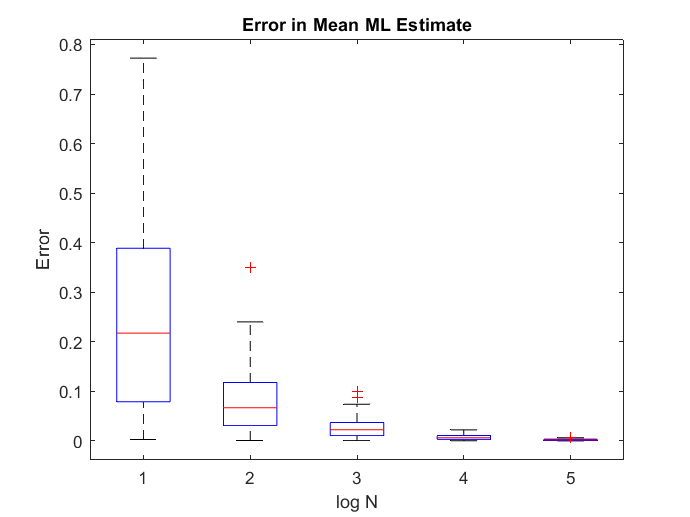

mean_errors = transpose(mean_errors);
cov_errors = transpose(cov_errors);

boxplot(mean_errors);
xlabel('log N');
ylabel('Error');
title('Error in Mean ML Estimate');

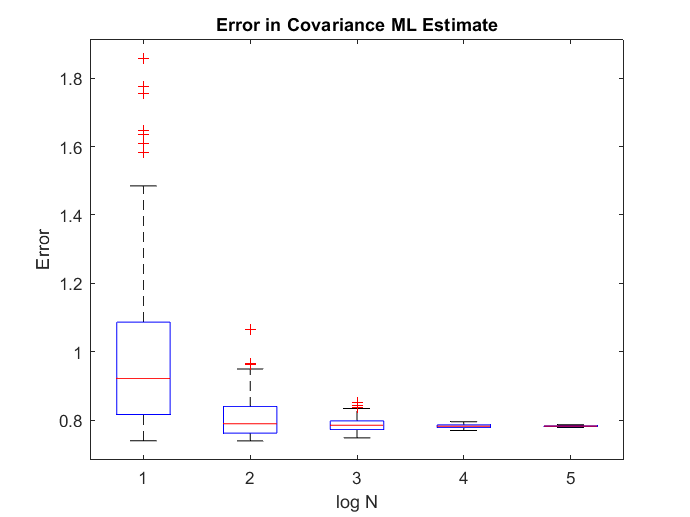


boxplot(cov_errors)
xlabel('log N');
ylabel('Error');
title('Error in Covariance ML Estimate');

(d) (5 points) For each value of N, for a single data sample, within a single figure, plot the 2D scatter plot of the generated data and show the principal modes of variation of the data by plotting a line starting at the empirical mean and going a distance equal to the empirical eigen-value’s square root along a direction given by the empirical eigen-vector

function arr = tempfun(x)
    arr = Q*(sqrt(D))*x;
end